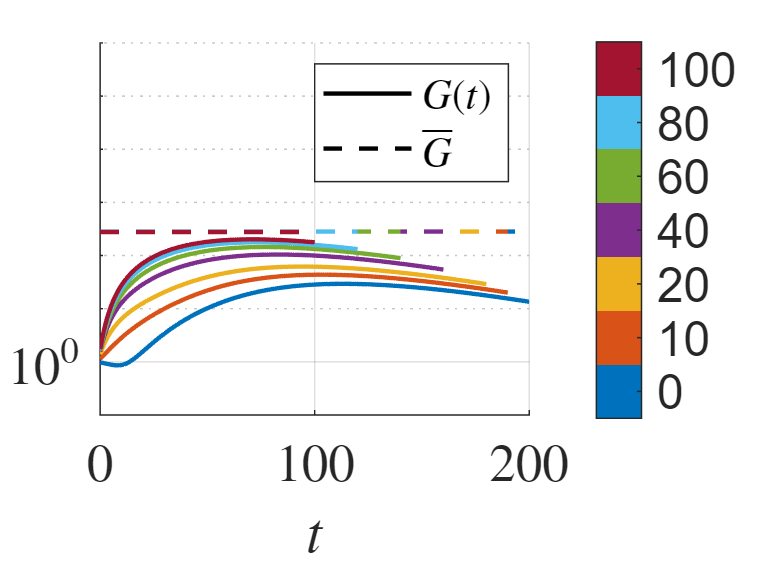

% Given data
t0 = [0, 10, 20, 40, 60, 80, 100];
% t0 = 20;
num_t0 = length(t0);
T = 200;
dt = 1;

% Create figure with log-scale Y-axis
figure;
set(gca, 'YScale', 'log');
hold on;

% Create colormap
cmap = lines(num_t0);
set(groot, 'defaultTextInterpreter', 'latex');
set(gca, 'TickLabelInterpreter', 'latex','FontSize',18);
% Plot settings
line_style = '-';   % Solid line for G_storage curves
dash_style = '--';  % Dashed line for constant lines

% Create dummy lines for legend
h1 = plot(NaN, NaN, 'k-', 'LineWidth', 1.5, 'DisplayName', '$G(t)$');
h2 = plot(NaN, NaN, 'k--', 'LineWidth', 1.5, 'DisplayName', '$\overline{G}$');

% Plot each G_storage{j} with its ttt_j
for j = 1:num_t0
    t_steps = (T - t0(j)) / dt;
    ttt_j = linspace(0, T - t0(j), t_steps);
    
    % Plot constant line (dashed)
    line([ttt_j(1), ttt_j(end)], [all_t_optimal(j), all_t_optimal(j)], ...
         'Color', cmap(j,:), 'LineStyle', dash_style, 'LineWidth', 1.5);
    
    % Plot G_storage curve (solid)
    plot(ttt_j, G_storage{j}, ...
         'Color', cmap(j,:), ...
         'LineStyle', line_style, ...
         'LineWidth', 1.5, ...
         'HandleVisibility', 'off');
end

% Configure colorbar with exact t0 values
c = colorbar;
colormap(cmap);
c.Ticks = linspace(0.5/num_t0, 1-0.5/num_t0, num_t0);
c.TickLabels = arrayfun(@(x) num2str(x), t0, 'UniformOutput', false);

% Axis limits and labels
xlim([0, 200]);
ylim([1e-1, 10^6]);
xlabel('$t$');
% ylabel('$G$');
grid on;

% Create legend showing both line styles
legend([h1, h2], 'Interpreter', 'latex', 'Location', 'northeast','FontSize',14);

hold off;

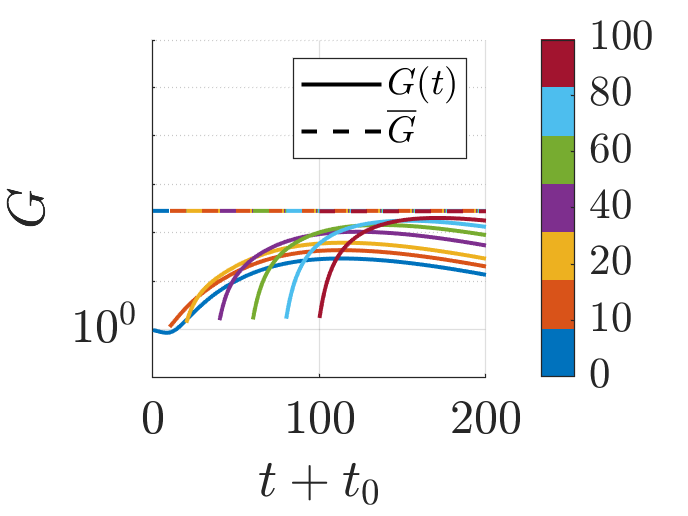




% Given data
t0 = [0, 10, 20, 40, 60, 80, 100];
num_t0 = length(t0);
T = 200;
dt = 1;

% Create figure with log-scale Y-axis
figure;
set(gca, 'YScale', 'log');
hold on;
set(groot, 'defaultTextInterpreter', 'latex');
set(gca, 'TickLabelInterpreter', 'latex', 'FontSize', 18);

% Create colormap
cmap = lines(num_t0);

% Plot settings
line_style = '-';   % Solid line for G_storage curves
dash_style = '--';  % Dashed line for constant lines

% Create dummy lines for legend
h1 = plot(NaN, NaN, 'k-', 'LineWidth', 1.5, 'DisplayName', '$G(t)$');
h2 = plot(NaN, NaN, 'k--', 'LineWidth', 1.5, 'DisplayName', '$\overline{G}$');

% Plot each G_storage{j} and constant line shifted by t0
for j = 1:num_t0
    t_steps = (T - t0(j)) / dt;
    ttt_j = linspace(t0(j), T, t_steps);  % Shifted time vector [t0(j), T]
    
    % Plot constant line (dashed)
    line([ttt_j(1), ttt_j(end)], [all_t_optimal(j), all_t_optimal(j)], ...
         'Color', cmap(j,:), 'LineStyle', dash_style, 'LineWidth', 1.5);
    
    % Plot G_storage curve (solid)
    plot(ttt_j, G_storage{j}, ...
         'Color', cmap(j,:), ...
         'LineStyle', line_style, ...
         'LineWidth', 1.5, ...
         'HandleVisibility', 'off');
end

% Configure colorbar with exact t0 values
c = colorbar;
colormap(cmap);
c.Ticks = linspace(0, 1, num_t0);  % Evenly spaced ticks
c.TickLabels = arrayfun(@(x) num2str(x), t0, 'UniformOutput', false);
% c.Label.String = 'Initial Time ($t_0$)';
c.Label.Interpreter = 'latex';
c.TickLabelInterpreter = 'latex';

% Axis limits and labels
xlim([0, 200]);
ylim([1e-1, 10^6]);
xlabel('$t + t_0$');
ylabel('$G$');
grid on;

% Create legend showing both line styles
legend([h1, h2], 'Interpreter', 'latex', 'Location', 'northeast', 'FontSize', 14);

hold off;